% this script determines a Homogeneous Transformation HT matrix
clear
% declaration of symbols
syms th1 a2 d3 al3 al4 th5 d5 q1 q4 q5
% determination of a symbolic form of HT matrices –
% application of mA function
A1=mA(th1,0,0,0)

$$A1 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\right) & -\sin\left({\mathrm{th}}_{1}\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{1}\right) & \cos\left({\mathrm{th}}_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2=mA(0,0,a2,0)

$$A2 = \left(\begin{array}{cccc} 1 & 0 & 0 & a_{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3=mA(sym(pi),-d3,0,sym(pi))

$$A3 = \left(\begin{array}{cccc} -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & -1 & -d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4=mA(sym(pi/2),0,0,al4)

$$A4 = \left(\begin{array}{cccc} 0 & -\cos\left({\mathrm{al}}_{4}\right) & \sin\left({\mathrm{al}}_{4}\right) & 0\\ 1 & 0 & 0 & 0\\ 0 & \sin\left({\mathrm{al}}_{4}\right) & \cos\left({\mathrm{al}}_{4}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A5=mA(th5,d5,0,0)    

$$A5 = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{5}\right) & -\sin\left({\mathrm{th}}_{5}\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{5}\right) & \cos\left({\mathrm{th}}_{5}\right) & 0 & 0\\ 0 & 0 & 1 & d_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% multiplication of matrices
T05=A1*A2*A3*A4*A5

$$T05 = \left(\begin{array}{cccc} \cos\left({\mathrm{al}}_{4}\right)\,\cos\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{5}\right)-\cos\left({\mathrm{th}}_{5}\right)\,\sin\left({\mathrm{th}}_{1}\right) & \sin\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{5}\right)+\cos\left({\mathrm{al}}_{4}\right)\,\cos\left({\mathrm{th}}_{1}\right)\,\cos\left({\mathrm{th}}_{5}\right) & -\sin\left({\mathrm{al}}_{4}\right)\,\cos\left({\mathrm{th}}_{1}\right) & a_{2}\,\cos\left({\mathrm{th}}_{1}\right)-d_{5}\,\sin\left({\mathrm{al}}_{4}\right)\,\cos\left({\mathrm{th}}_{1}\right)\\ \cos\left({\mathrm{th}}_{1}\right)\,\cos\left({\mathrm{th}}_{5}\right)+\cos\left({\mathrm{al}}_{4}\right)\,\sin\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{5}\right) & \cos\left({\mathrm{al}}_{4}\right)\,\cos\left({\mathrm{th}}_{5}\right)\,\sin\left({\mathrm{th}}_{1}\right)-\cos\left({\mathrm{th}}_{1}\right)\,\sin\left({\mathrm{th}}_{5}\right) & -\sin\left({\mathrm{al}}_{4}\right)\,\sin\left({\mathrm{th}}_{1}\right) & a_{2}\,\sin\left({\mathrm{th}}_{1}\right)-d_{5}\,\sin\left({\mathrm{al}}_{4}\right)\,\sin\left({\mathrm{th}}_{1}\right)\\ -\sin\left({\mathrm{al}}_{4}\right)\,\sin\left({\mathrm{th}}_{5}\right) & -\sin\left({\mathrm{al}}_{4}\right)\,\cos\left({\mathrm{th}}_{5}\right) & -\cos\left({\mathrm{al}}_{4}\right) & -d_{3}-d_{5}\,\cos\left({\mathrm{al}}_{4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% substitution of rotational joint variables
% for the simplification purpose
T05v=subs(T05,{th1,al4,th5},{q1,q4,q5});
% indication of joint coordinates
% variables: th1,th2 and a3 indicated by ‘1’s
zmie=[[1,0,0,0];[0,0,1,0];[0,1,0,0];[0,0,0,1];[1,0,0,0]]

zmie =      1     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     1
     1     0     0     0


% a simplified form of the evaluated HT matrices
% for interpretation purpose for a user
T05u=zam(zmie,T05v,'q')

% example of substitution of the joint variables’ values
% and constant values into the T0e matrix for the RRP manipulator example
% please use meters and radians
T05n=double(subs(T05,{th1,a2,d3,al4,th5,d5},{pi/3,0.8,0.6,4*pi/6,pi/3,0.3}))

T05n =    -0.6495    0.6250   -0.4330    0.2701
   -0.1250   -0.6495   -0.7500    0.4678
   -0.7500   -0.4330    0.5000   -0.4500
         0         0         0    1.0000


% T05n=double(subs(T05,{th1,a2,d3,al3,al4,th5,d5},{pi/3,0.8,pi,0.6,pi/3,pi,pi/2,0,4*pi/6,0.2}))

th1 jest var i obracamy z 0 na 60st

a2 jest var i trans z 0.6 na 0.8

d3 jest var i trans 0.4 na 0.6

al4 jest var z 90st na 120st

th5 jest var i obracamy z 0 na 60stop

% [theta d a alpha]
% [a alpha d theta]
dhparams=[0,0,0,pi/2
    0.8,0,0,0
    0,pi,0.6,pi
    0,4*pi/6,0,pi
    0,0,0.3,pi/3];

% dhparams=[pi/3,0,0,0
%     0,0,0,0.8
%     ]

disp(dhparams)

         0         0         0    1.5708
    0.8000         0         0         0
         0    3.1416    0.6000    3.1416
         0    2.0944         0    3.1416
         0         0    0.3000    1.0472



robot = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;

addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','prismatic');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');


setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');
setFixedTransform(jnt5,dhparams(5,:),'dh');



body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;


addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')

showdetails(robot);

--------------------
Robot: (5 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2    prismatic            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   
--------------------


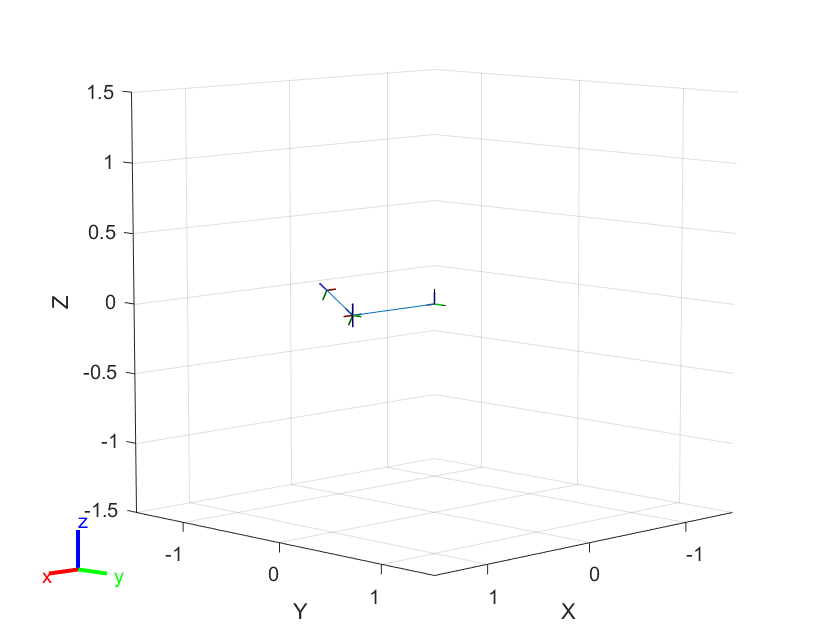

show(robot);

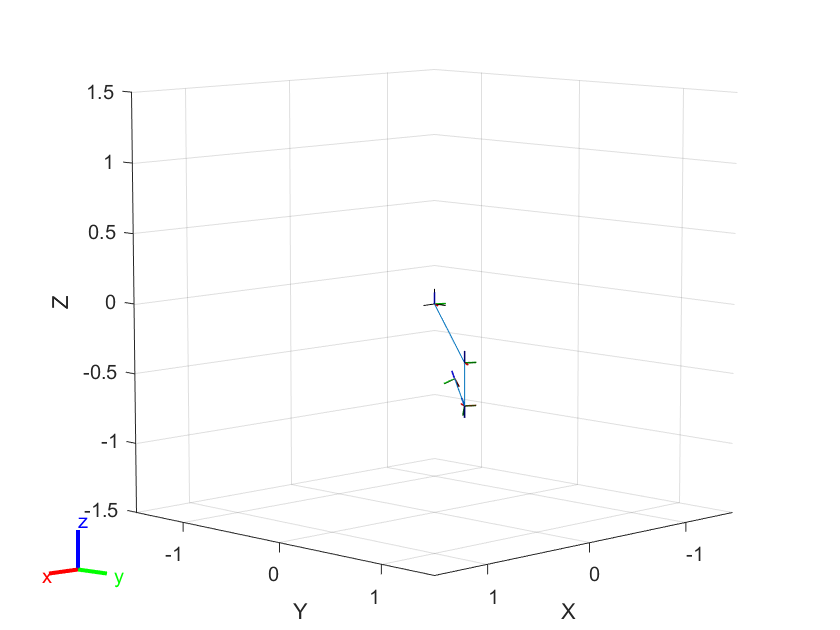

tform = T05n;
    
ik=inverseKinematics('RigidBodyTree',robot);
weights = [0.25 0.25 0.25 0.25 0.25 0.25];
initialguess = robot.homeConfiguration;
[configSoln,solnInfo] = ik('body5',tform,weights,initialguess);
figure()
show(robot,configSoln);

figure()
show(robot,configSoln);

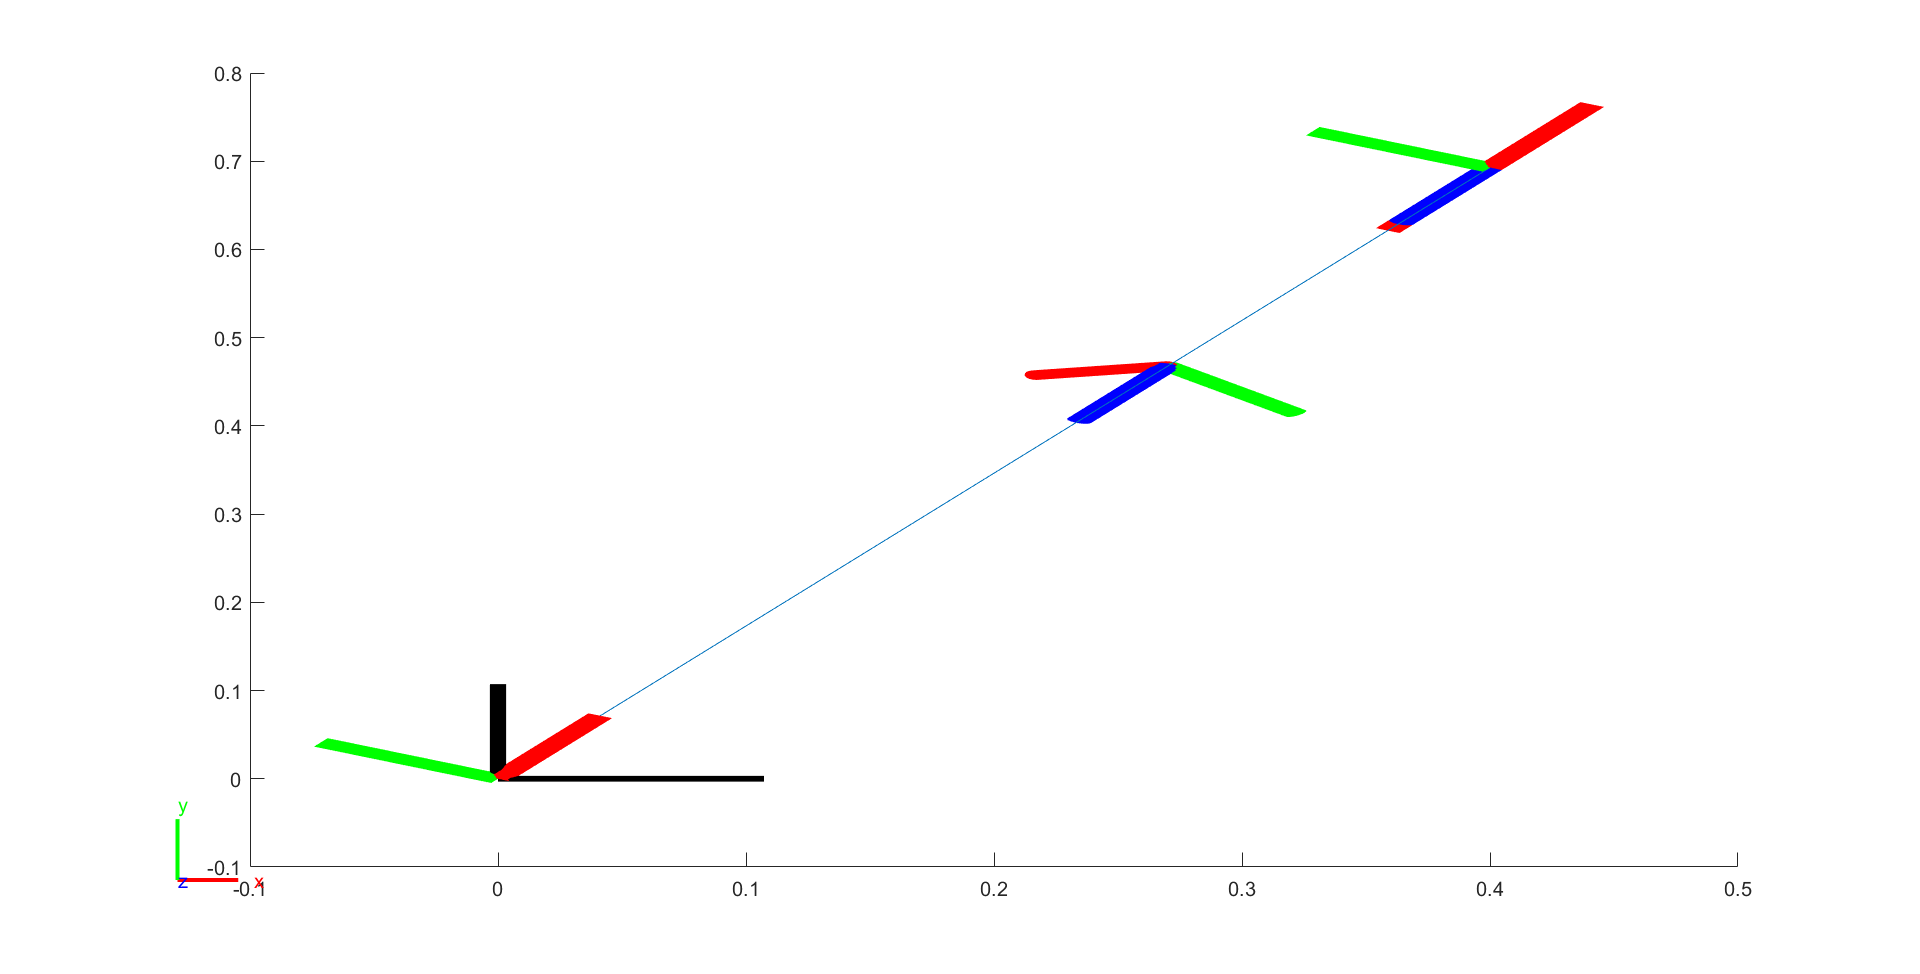

figure()
view(2); hold on

show(robot,configSoln);
view(0,90);

jointAngles=configSoln;
